flowerds = imageDatastore('Flowers','IncludeSubfolders',true,'LabelSource','foldernames');

[trainImgs,testImgs] = splitEachLabel(flowerds,0.6);
numClasses = numel(categories(flowerds.Labels));
net = alexnet;
layers = net.Layers;
layers(end-2) = fullyConnectedLayer(numClasses);
layers(end) = classificationLayer;
options = trainingOptions('sgdm','InitialLearnRate', 0.001);

[flowernet,info] = trainNetwork(trainImgs, layers, options);

Training on single GPU.
Initializing image normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:05 |        4.69% |       3.9194 |          0.0010 |
|      13 |          50 |       00:00:17 |      100.00% |       0.0080 |          0.0010 |
|      25 |         100 |       00:00:29 |      100.00% |       0.0025 |          0.0010 |
|      30 |         120 |       00:00:33 |      100.00% |       0.0048 |          0.0010 |
|========================================================================================|


testpreds = classify(flowernet,testImgs);
nnz(testpreds == testImgs.Labels)/numel(testpreds)

ans = 0.8932

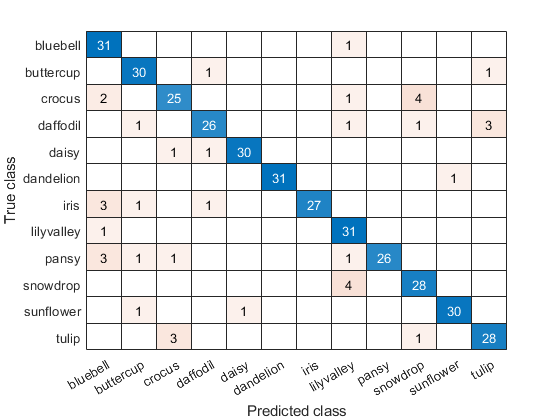

confusionchart(testImgs.Labels,testpreds);